Formula lui Taylor si aplicatii (aproximare Pade)

Config

syms x;

### Probelma 5

taylor(@(x) log(1+x), x, 0)

$$ans = x-\frac{x^{2}}{2}+\frac{x^{3}}{3}-\frac{x^{4}}{4}+\frac{x^{5}}{5}$$

### Problema 6

taylor(@(x) atan(x), x, 0, 'Order', 12)

$$ans = x-\frac{x^{3}}{3}+\frac{x^{5}}{5}-\frac{x^{7}}{7}+\frac{x^{9}}{9}-\frac{x^{11}}{11}$$

syms n;
f(n)=(sym(pi)/4)^(2*n+3)./(2*n+3);
vpa(double(f((1:25)')))

$$ans = \left(\begin{array}{c} 0.05976946968462528569920877430377\\ 0.026334867011167620298728309080616\\ 0.012634743302004586631981375433043\\ 0.0063767003573914141090206442186172\\ 0.0033283202357169338822528992238858\\ 0.0017793318858611085250126526702275\\ 0.00096845414402721094210974017713056\\ 0.00053450792038306320363982848675732\\ 0.00029831027602728044101354498707224\\ 0.00016801166488192824247441259366553\\ 0.000095346998361299194744457319306008\\ 0.000054458168672299671439918783422129\\ 0.000031275809682094132271011621693191\\ 0.000018047814914707368139784593452646\\ 0.00001045808446757481472788944842911\\ 0.0000060824395787654312621668163674205\\ 0.000003549146174422329388519099790944\\ 0.0000020770204199005754193993553841091\\ 0.0000012187125384431772006786805218059\\ 0.00000071679743598305847043062428644578\\ 0.0000004225052868629477324666438367573\\ 0.0000002495321831672515947790191165323\\ 0.0000001476413837505666724063169191819\\ 0.000000087501152563147399215462960732348\\ 0.000000051938313422546199491393049659307 \end{array}\right)$$

dT(x)=taylor(@(x) atan(x), x, 0, 'Order', 34);
vpa(double(dT(sym(pi)/4)))

$$ans = 0.66577759273252690164213163370732$$

vpa(double(atan(sym(pi)/4)))

$$ans = 0.66577375002835381678778503555804$$

### Problema 7

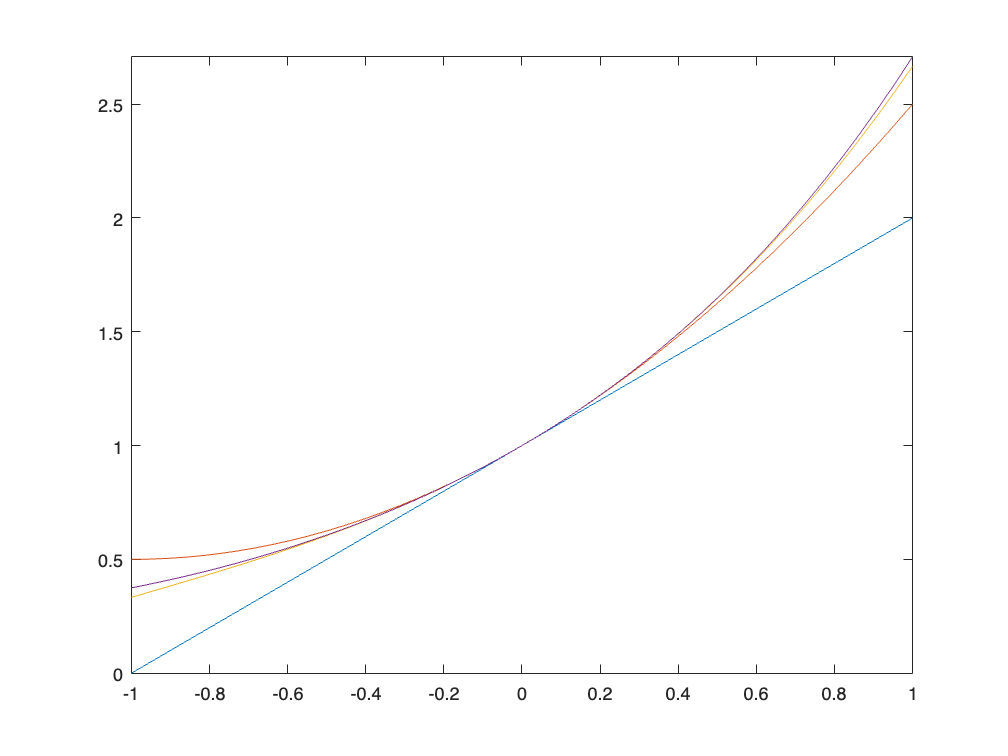

f(x) = exp(x);
T2 = taylor(f, x, 0, 'Order', 2);
T3 = taylor(f, x, 0, 'Order', 3);
T4 = taylor(f, x, 0, 'Order', 4);
T5 = taylor(f, x, 0, 'Order', 5);
fplot([T2, T3, T4, T5], [-1, 1])

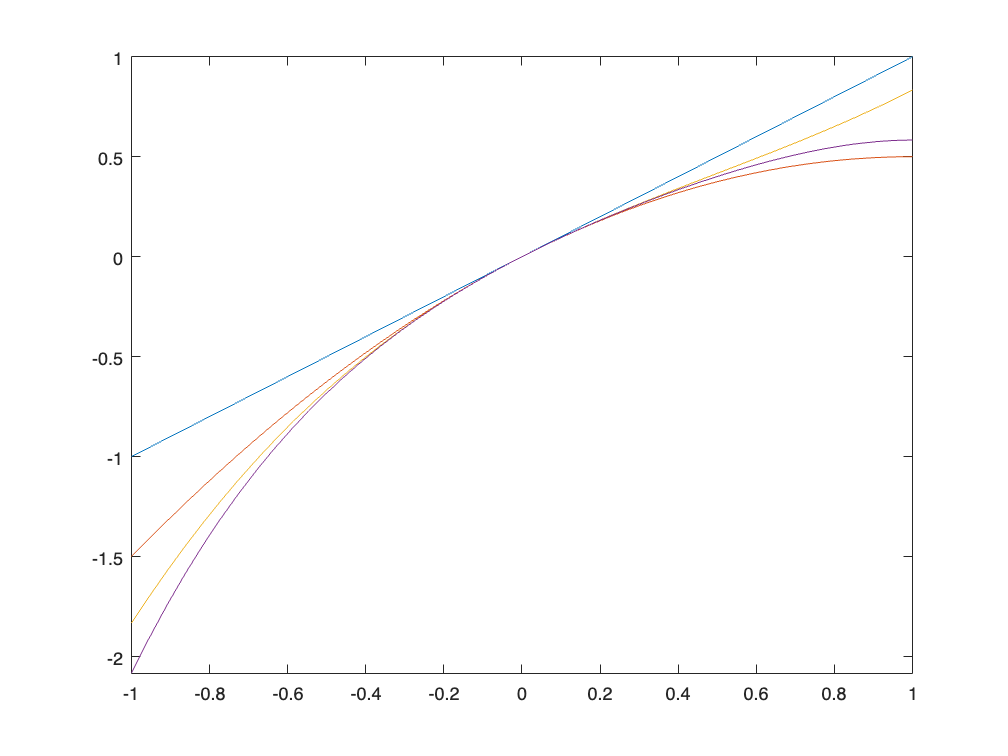

g(x) = log(1+x);
T2 = taylor(g, x, 0, 'Order', 2);
T3 = taylor(g, x, 0, 'Order', 3);
T4 = taylor(g, x, 0, 'Order', 4);
T5 = taylor(g, x, 0, 'Order', 5);

fplot([T2, T3, T4, T5], [-1, 1])

clear;
syms x;
f(x) = exp(x);
m = 2;
k = 2;
x0 = 1;
syms C a R bt vp
c = zeros(m+k+1, 1, 'sym');
if m > k
    b = zeros(m+1, 1, 'sym');
else 
    b = zeros(k+1, 1, 'sym');
end
a = zeros(1, m + 1, 'sym');

for p=0:m+k
    c(p+1)=subs(diff(f,x,p),x, x0)/factorial(p); % here we replace a
end

j=0:k-1;
C=toeplitz(c(m+j+1),c(m-j+1));
bv=-c(m+(1:k)+1);
b(2:k+1)=C\bv;
b(1)=1;

for j=0:m
    a(j+1)=sym('0');
    for l=0:j
        a(j+1)=a(j+1)+c(j-l+1)*b(l+1); 
    end
end
vp=sum(a.*(x-x0).^(0:m));
vq=sum(b(1:k+1)'.*(x-x0).^(0:k));
rez = vp/vq;
simplifyFraction(rez)

$$ans = \frac{7\,\mathrm{e}+4\,\mathrm{e}\,x+\mathrm{e}\,x^{2}}{19-8\,x+x^{2}}$$

Restul in forma Lagrange 

f(x) = sin(x);
a = 0;
n = 10;
syms xi R 
if subs(diff(f,x,n),x,a)==0
    R=x^(n+1)/factorial(n+1)*subs(diff(f,x,n+1),x,xi);
else
    R=x^n/factorial(n)*subs(diff(f,x,n),x,xi);
end
y=taylor(f,x,a,'Order',n)+R

$$y(x) = x-\frac{x^{11}\,\cos\left(\xi \right)}{39916800}-\frac{x^{3}}{6}+\frac{x^{5}}{120}-\frac{x^{7}}{5040}+\frac{x^{9}}{362880}$$